dW = Coordinate(n.left(2),2)-Coordinate(n.left(1),2);
dL = dW;

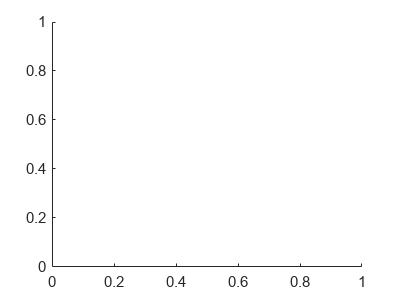

iNode = 1:20; % 绘制的节点编号
iNode = n.left; % 左边界节点
% iNode = n.right; % 右边界节点
iNode = n.sampling;
t = 1e-1; % 动画帧时间

figure()
for ii = 1:length(iNode)
	i = iNode(ii);
	plot(Coordinate(i,1),Coordinate(i,2),'.','MarkerSize',10)
	xlim([min(Coordinate(iNode,1)-dL),max(Coordinate(iNode,1))+dL])
	ylim([min(Coordinate(iNode,2)-dW),max(Coordinate(iNode,2))+dW])
	text(Coordinate(i,1),Coordinate(i,2),num2str(i),'FontSize',6,'VerticalAlignment','top','HorizontalAlignment','left')
	pause(t)
	hold on
end
% axis padded
hold off

%{
iElement = 1599;
% iElement = 1:2;
% iElement = Nelement-1:Nelement; % 绘制的单元编号


t = 5e-1; % 动画帧时间

figure()
nodes = Ielement(iElement,:);
plot(nan,nan)
hold on
xlim([min(Coordinate(nodes(:),1)-dL),max(Coordinate(nodes(:),1))+dL]);
ylim([min(Coordinate(nodes(:),2)-dW),max(Coordinate(nodes(:),2))+dW]);

for i = 1:length(iElement)
	draw(iElement(i),t,Ielement,Coordinate)
end
hold off
%}

function draw(iElement,t,Ielement,Coordinate)
% global Ielement Coordinate
ele1 = Ielement(iElement,:);
for i = 1:length(ele1)
	plot(Coordinate(ele1(i),1),Coordinate(ele1(i),2),'.','MarkerSize',10)
	text(Coordinate(ele1(i),1),Coordinate(ele1(i),2),num2str(ele1(i)))
	pause(t)
end
end